# Accessing the Spectral module through Matlab 2019b

This notebooks is a simple example on how to call various methods from the Spectral python library.

## Importing python libraries

Python libraries can be imported using the importlib util. To make sure your python interpreter is configured correctly, use "`py.help('numpy')`" to ensure all required dependencies are in your path.

If that returns a list of NumPy methods along with a version and path, we're good to go. Start by importing the necessary python modules

% Import libraries
np = py.importlib.import_module('numpy');
sc = py.importlib.import_module('src.spectral.contrast');

### Passing keyword arguments to Python

Python converts keyword arguments to dictionaries. For Matlab users, keyword arguments need to be converted to a python object using `pyargs`. This function coverts Matlab keywords to Python keywords, enabling smooth passing of arguments.

Use "`doc pyargs"` for more details.

% Specify keyword arguments for python methods
args_gen = pyargs('fs', int32(1000), 'nchans', int32(10), 'nsamples', int32(2000));

args_gen =   pyargs with no properties.



% Use it to call a method
data = sc.simulate_recording(args_gen);
y = [ones(1,5), zeros(1,5)];

% Specify data-specific arguments
args_con = pyargs('fs', int32(1000), 'nperseg', int32(64));
res = sc.contrast(data, y, args_con);

We've captured the result returned by `sc.contrast()` in `res`. In case we'd like to know what `sc.contrast()` returns, we can always invoke Python's help command (since the funtion is in Python).

py.help(sc.contrast)

Help on function contrast in module src.spectral.contrast:

contrast(data, y, **kwargs)
    This method returns the SNR given a data array and vector of labels.
    
    Ideally, this should be the only method that you need to call when contrasting timeseries' spectra.
    
    Parameters
    ----------
    data: array [nchans x nobs x ntrials]
        an array with the LFP data organized into channels and trials.
    y: array [ntrials]
        a binary vector with a label for each trial being either 0 or 1
    
    **fs: int
        the sampling frequency of the signal
    **nperseg: param (int)
        number of samples per fft
    **noverlap: param (int)
        number of samples of overlap between successive ffts
        
    Returns
    -------
    snr: array [nfreqs x nfreqs]
        a matrix with the SNR for each combination of frequency bands
    f: array [nfreqs]
        a vector that represents the frequencies for interpreting `snr`.



The docstring says that it returns two arrays, snr and f. If we check the Matlab Workspace, we see that '`res'` has a value: `1x2 tuple`.

The original arrays can be retrieved by indexing into res.

res(2)

ans =   Python tuple with no properties.

    (array([  0.   ,  15.625,  31.25 ,  46.875,  62.5  ,  78.125,  93.75 ,
           109.375, 125.   , 140.625, 156.25 , 171.875, 187.5  , 203.125,
           218.75 , 234.375, 250.   , 265.625, 281.25 , 296.875, 312.5  ,
           328.125, 343.75 , 359.375, 375.   , 390.625, 406.25 , 421.875,
           437.5  , 453.125, 468.75 , 484.375, 500.   ]),)


Python returns results to Matlab as Python objects. These need to be cast into Matlab compatible variables. There is no default code for this, and you need to ensure you know what the Python method's return.

In this case, we know contrast returns snr, and f. And we know these are arrays. So we can retrieve their Matlab compatible versions:

% convert arrays back to matlab-readable formats
snr = np.array(res(1)) % convert tuple-object into Numpy array
snr = double(snr) % convert numpy array into Matlab array
snr = squeeze(snr);

Python sometimes adds metadata to arrays for more information, but in our case, the extra dimension is empty, so we just squeeze the arrays.

We can do all the above steps together in a single step:

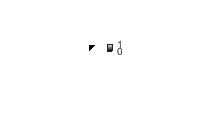

f = squeeze(snr); % remove extra dimensions

Plotting the snr is super easy,

imshow(flipud(snr));